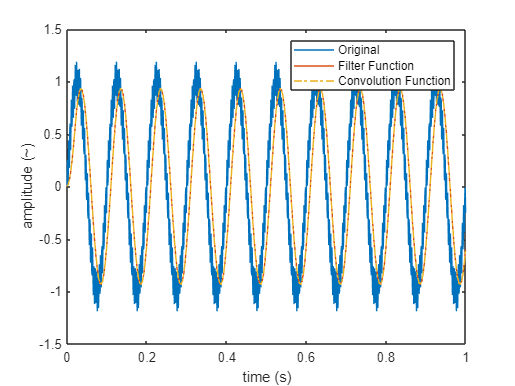

%% Lab 2
clear all

%% Task 1
%Ex. 1.1
fs = 1000; % sampling frequency
N = 1000; % number of samples
t = (0:N-1)/fs; % time range
f1 = 10; %frequency one
f2 = 300; %frequency two
a1 = 1; % amplitude one
a2 = 0.2; % amplitude two
y = a1*sin(2*pi*f1*t) + a2*sin(2*pi*f2*t); 

%Rectangular Window
h = 1/21*rectwin(21);
%wvtool(h)
%Applying Convolution
yc = conv(y,h);
yc = yc(1:1000);
%Filter function
yf = filter(h,1,y);
Yf=fft(yf);
Y=fft(y);
N=length(yf);
df=fs/N;
fv=(0:N-1)*df;
figure(2)
plot(t,y)
hold on
plot(t,yf)
plot(t,yc,'-.')
hold off
xlabel('time (s)');
ylabel('amplitude (~)');
legend('Original','Filter Function', 'Convolution Function');

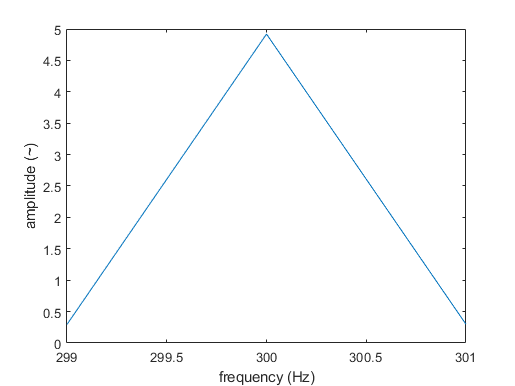

figure(13)
plot(fv(1:fs/2),abs(Yf(1:fs/2)))
xlim([299,301])
xlabel('frequency (Hz)');
ylabel('amplitude (~)');

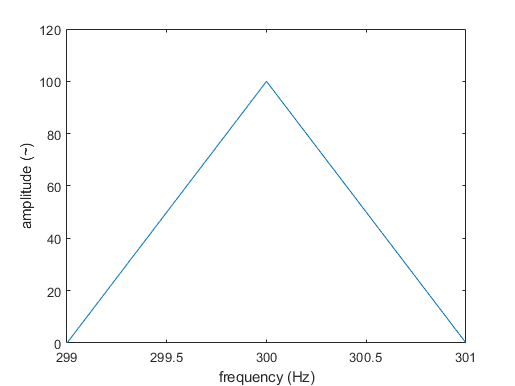

figure(14)
plot(fv(1:fs/2),abs(Y(1:fs/2)))
xlim([299,301])
xlabel('frequency (Hz)');
ylabel('amplitude (~)');

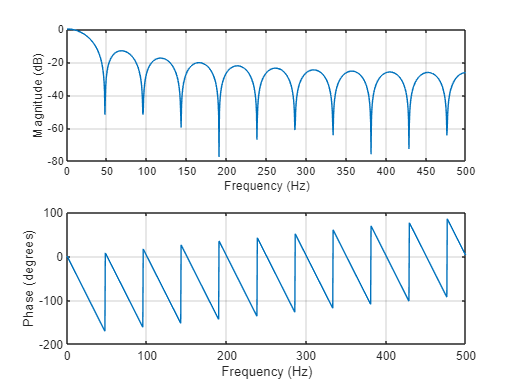


%Freqz Filter
figure(3)
freqz(h,1,N,fs);

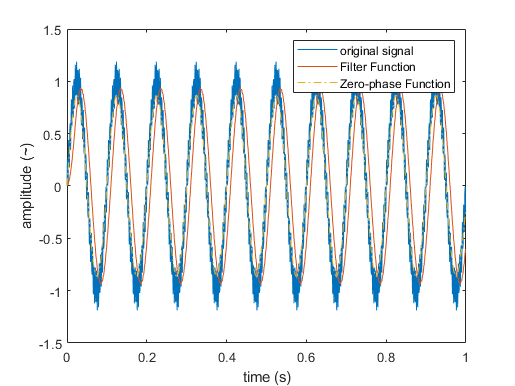


%Ex. 1.2
yz = filtfilt(h,1,y);
figure(4)
plot(t,y)
hold on
plot(t,yf)
plot(t,yz,'-.')
hold off
xlabel('time (s)')
ylabel('amplitude (~)')
legend('original signal','Filter Function', 'Zero-phase Function') % whats noticed here is group delay

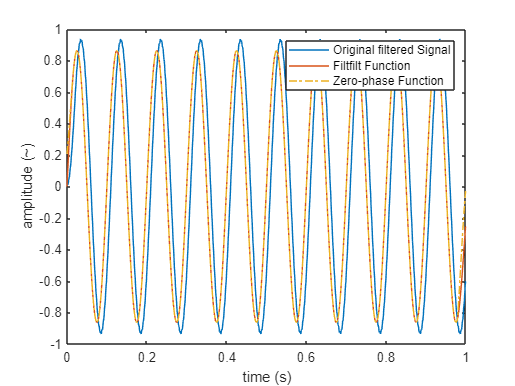


yc2 = filter(h,1,y);
yc_reverse = yc2(end:-1:1);
yc_rev_conv =  filter(h,1,yc_reverse);
yz2 = yc_rev_conv(end:-1:1);
yz2 = yz2(1:1000);

figure(5)
plot(t,yf)
hold on
plot(t,yz)
plot(t,yz2,'-.')
hold off
xlabel('time (s)')
ylabel('amplitude (~)')
legend('Original filtered Signal','Filtfilt Function', 'Zero-phase Function')

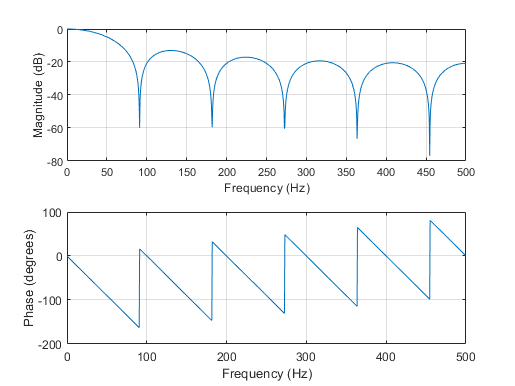


%Ex. 1.3
h2 = 1/11*rectwin(11);
figure(6)
freqz(h2,1,N,fs);

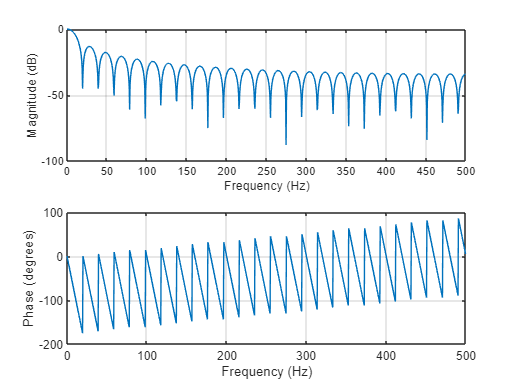

figure(7)
h3 = 1/51*rectwin(51);
freqz(h3,1,N,fs);

figure(8)

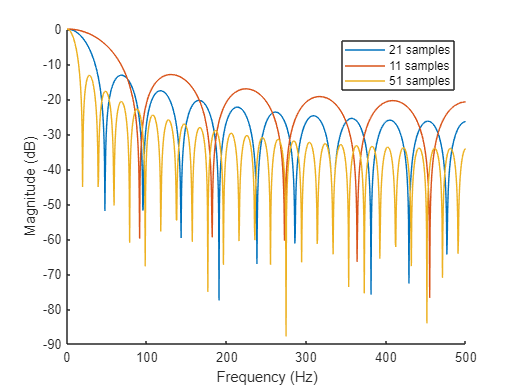


[h11,ph1]=freqz(h,1,N,fs);
[h22,ph2]=freqz(h2,1,N,fs);
[h33,ph3]=freqz(h3,1,N,fs);
h_fin=[h11,h22,h33];
ph=[ph1,ph2,ph3];
figure
hold on
for i= 1:1:3
    plot(ph(:,i),20*log10(abs(h_fin(:,i))));
end 
legend('21 samples','11 samples','51 samples')
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
hold off